# **Procesarea imaginilor - Transformari ale nivelului de gri **

## **Notiuni generale**

- evidențierea trăsăturilor pe baza manipulării contrastului

- ex: **algoritmi de detectie a fetei**

###     a. Corectarea nivelului de gri dependent de pozitia pixelului în imagine

- întâlnit de obicei în situațiile în care imaginea este distorsionată din cauza dispozitivului de achiziție sau a iluminării precare a scenei

###     b. Modificarea scalei nivelului de gri

- trecerea de la un anumit interval de valori de gri la unul dorit de utilizator pentru evidentierea anumitor trasaturi

- Concept important: **HISTOGRAMA**

#### **            HISTOGRAMA**

- **frecvența** de **apariție ** a unui **nivel **de** gri**

- **în MATLAB: *****imhist***

 **Exemplu:**

% citirea imaginilor "coins.png" și "peppers.png"(gray)
im1 = imread('coins.png');
im2 = imread('peppers.png');
im2g = rgb2gray(im2);
% Cerință: afișare histogramei alături de imaginea inițială






% rezolvare
figure(1); 
subplot(2,2,1); imshow(im1);
subplot(2,2,2); imhist(im1);
subplot(2,2,3); imshow(im2g);
subplot(2,2,4); imhist(im2g);

**Transformări dinamice ale histogramei: **

- **tranformarea logaritmică: **

-     regiunile întunecate ale imaginii vor fi extinse, iar contrastul acestor regiuni va fi îmbunătățit. 

-     logaritmul crește ratele de schimbare pentru valori mici ale pixelilor, ceea ce face ca diferențele subtile între aceste valori să fie mai vizibile în imaginea rezultată. 

-     utilă în special în imagini cu iluminare slabă sau cu contraste reduse, unde detalii importante pot fi pierdute în zonele întunecate,

- **transformarea "contrast-stretching":**

-     îmbunătățește detaliile din imagine printr-o iluminare generală a acesteia

### Matlab functions

## histeq

- accentuarea contrastului prin obtinerea unei histograme uniforme

## exemplu 1

I1 = imread('coins.png');

I2 = histeq(I1,10);
subplot(221);imshow(I1);
subplot(222);imhist(I1);
subplot(223);imshow(I2);
subplot(224);imhist(I2);



## exemplu 2 - mult fundal

I1 = imread('tire.tif');
I2 = histeq(I1);
subplot(221);imshow(I1);
subplot(222);imhist(I1);
subplot(223);imshow(I2);
subplot(224);imhist(I2);


## exemplu 3 - constrast slab

I1 = imread('pout.tif');
I2 = histeq(I1);
subplot(221);imshow(I1);
subplot(222);imhist(I1);
subplot(223);imshow(I2);
subplot(224);imhist(I2);


## exemplu 4 - nu imbunatateste contrastul

I1 = imread('L4_image01.tif');
I2 = histeq(I1);
subplot(221);imshow(I1);
subplot(222);imhist(I1);
subplot(223);imshow(I2);
subplot(224);imhist(I2);


## exemplul 5 - imbunatateste partial contrastul

I1 = imread('L4_image02.tif');
I2 = histeq(I1);
subplot(221);imshow(I1);
subplot(222);imhist(I1);
subplot(223);imshow(I2);
subplot(224);imhist(I2);

## imadjust

## exemplul 1

img1 = imread('L4_image01.tif');
% imaginea originala
subplot(3,2,1); imshow(img1);
subplot(3,2,2); imhist(img1)
% ajustare default + histograma
J = imadjust(img1);
subplot(3,2,3); imshow(J);
subplot(3,2,4); imhist(J);
% ajustare cu parametrii + histograma
K = imadjust(img1,[50/255 200/255],[0 1]);
subplot(3,2,5); imshow(K);
subplot(3,2,6); imhist(K);


## exemplul 2

img1 = imread('L4_image02.tif');

subplot(2,2,1); imshow(img1);
subplot(2,2,2); imhist(img1);

I = imadjust(img1,[170/255 250/255],[0 1]);
subplot(2,2,3); imshow(I);
subplot(2,2,4); imhist(I);


## exemplul 3 - adapthisteq

I1 = imread('car_4.jpg');
I2 = rgb2gray(I1);
I3 = imadjust(I2,[0 30/255]);
figure()
imshow(I3);
I4 = adapthisteq(I2);
imshow(I4);

## Exercitiul 1

% Scrieți o funcție care să realizeze negativul unei imagini primite ca
% parametru

initImg = imread('coins.png');
negImg = negativeImage(initImg);
figure; 
subplot(1,2,1);
imshow(initImg);
title("Initial Image");
subplot(1,2,2);
imshow(negImg);
title("Negative Image");


## varianta simpla cu functie din laborator


I1 = imread('peppers.png');
I2 = rgb2gray(I1);
I3 = im2bw(I2);
I1c = imcomplement(I1);
I2c = imcomplement(I2);
I3c = imcomplement(I3);
figure(1)
subplot(3,2,1); imshow(I1);
subplot(3,2,2); imshow(I1c);
subplot(3,2,3); imshow(I2);
subplot(3,2,4); imshow(I2c);
subplot(3,2,5); imshow(I3);
subplot(3,2,6); imshow(I3c);


## Exercitiul 2

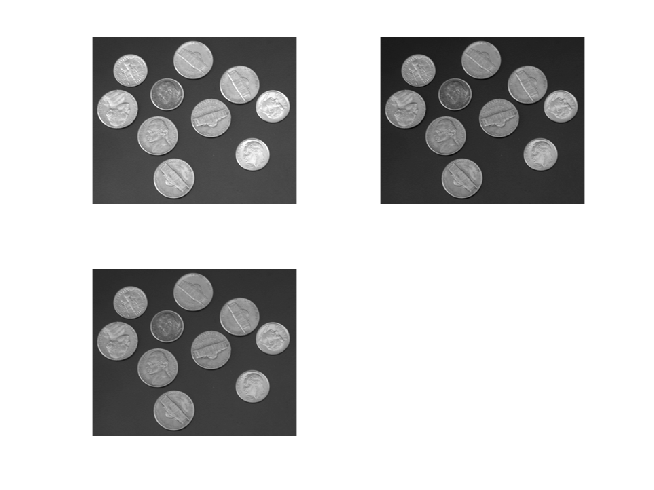

% Optimizati exemplul din aceasta lucrare realizand 
% un tablou cu nuante de gri pentru a elimina calculul succesiv 
img = imread('coins.png');
newImage1 = StretchHistogram(img, 5, 200);
newImage2 = StretchHistogramOptimized(img, 5, 200);
figure()
subplot(221); imshow(img);
subplot(222); imshow(newImage1);
subplot(223); imshow(newImage2);

## Exercitiul 3

% Realizaţi trei funcţii matlab care să modifice nuanţele de gri 
% după cele trei grafice din figura

i1 = imread('coins.png');I = imread('coins.png');
a = 50;
b = 200;

% graficul 1
% i1(i1<=a) = linspace(0, a, numel(i1(i1<=a)));
% i1(i1> a & i1<b) = linspace(a, b, numel(i1(i1> a & i1<b)));
% i1(i1>=b) = linspace(b, 255, numel(i1(i1>=b)));
% imshow(i1)
% imhist(i1)

%graficul 1
[m,n]=size(I);
for i = 1 : m 
    for j = 1 : n 
        if I(i, j) < a
            I(i,j) = 30 * I(i, j) / a;
        end

        if I(i, j) > a && I(i, j) < b
            I(i,j) = 30 + ((195 * (I(i, j) - a))/(b - a));
        end

        if I(i, j )>= b
            I(i,j) = 225 + ((30 * (I(i, j) - b))/(255 - b));
        end
    end   
end
imshow(I);
figure
imhist(I);

i2 = imread('coins.png');
%graficul 2
i2(i2<=a) = 0;
i2(i2> a & i2<b) = 255/2;
i2(i2>=b) = 255;
imshow(i2)
imhist(i2)

i3 = imread('coins.png');
%graficul 3
figure
imshow(i1);
[m,n] = size(I);
for i = 1 : m
    for j = 1 : n
        i1(i,j) = 225 - 195*double(I(i,j))/255;
    end
end
figure
imshow(uint8(i1))
figure
imhist(i1)

## Exercitiul 4

% Sa se realizeze o functie pentru afisarea histogramei normalizate

function normHist = normalizedHist(image)
    % Calculează histograma imaginii
    [counts, ~] = imhist(image);
    
    % Calculează numărul total de pixeli din imagine
    totalPixels = numel(image);
    
    % Normalizează histograma împărțind fiecare bin la numărul total de pixeli
    normHist = counts / totalPixels;
end

%% f

function negImg = negativeImage(initialImage)
    % determine the size of initial image
    [m, n] = size(initialImage);
    
    % determine the minimum and maximum values in the initial image
    minVal = min(initialImage(:));
    maxVal = max(initialImage(:));

    % allocate memory for the negative image
    negImg = initialImage * 0;

    % implement general formula for each pixel to determine the negative
    for i = 1:m
        for j = 1:n
            negImg(i, j) = maxVal - (initialImage(i,j) - minVal);
        end
    end
end

function newImage = StretchHistogram(image, qMin, qMax)
    pMin = min(min(image));
    pMax = max(max(image));
    imageSize = size(image);
    newImage = image;
    for i = 1 : imageSize(1)
        for j = 1 : imageSize(2)
            newImage(i,j) = uint8(double(qMin) + ...
                            (double(image(i,j)) - double(pMin))* ...
                            (double(qMax)-double(qMin))/...
                            (double(pMax)-double(pMin)));
        end
    end
end


function newImage = StretchHistogramOptimized(image, qMin, qMax)
    % determinarea valorilor minime si maxime
    imageSize = size(image);
    newImage = image * 0;
    
    % paleta proprie de culori implementata ca lookupTable
    lookupTable = uint8((0:255) * (qMax - qMin) / 255 + qMin);

    % parcurgerea imaginii
    for i = 1 : imageSize(1)
        for j = 1 : imageSize(2)
            % atribuirea cu valori din lookupTable
            newImage(i, j) = lookupTable(image(i, j));
        end
    end
    % Converteste imaginea la tipul uint8
    newImage = uint8(newImage);
end
